# Lecture 18

## Exercise 6

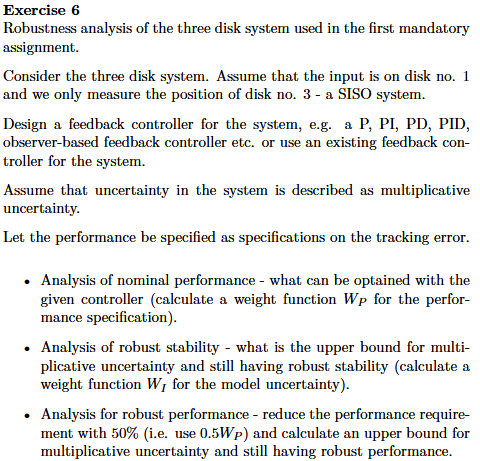

clear all; clc;

syms f_theta1 f_theta2 f_theta3 f_u1 f_u2 theta1 omega1 theta2 omega2 theta3 omega3 u1 u2 y1 y2 y3

load('ECP_values.mat');

J_1 = ECP_values(1);            % Disk 1 inertia kgm^2
J_2 = ECP_values(2);            % Disk 2 inertia kgm^2
J_3 = ECP_values(3);            % Disk 3 inertia kgm^2
k_1 = ECP_values(4);            % Shaft 1-2 stiffness Nm/rad
k_2 = ECP_values(5);            % Shaft 2-3 stiffness Nm/rad
b_1 = mean(ECP_values([6 7]));  % Disk 1 damping and friction Nms/rad
b_2 = mean(ECP_values([8 9]));  % Disk 2 damping and friction Nms/rad
b_3 = mean(ECP_values([10 11]));% Disk 3 damping and friction Nms/rad

x = [theta1 omega1 theta2 omega2 theta3 omega3].';
u = [u1 u2].';
y = [y1 y2 y3].';
f = [f_theta1 f_theta2 f_theta3 f_u1 f_u2].';
A = [0, 1, 0, 0, 0, 0;
     -k_1/J_1, -b_1/J_1, k_1/J_1, 0, 0, 0;
     0, 0, 0, 1, 0, 0;
     (k_1/J_1), 0, -(k_1 + k_2)/J_1, (-b_2/J_1), -k_2/J_1, 0;
     0, 0, 0, 0, 0, 1;
     0, 0, -k_2/J_1, 0, k_2/J_1, b_3];
B = [0 0
     1/J_1 0
     0 0
     0 0
     0 0
     0 0];
C = [0 0 0 0 0 0
     0 0 0 0 0 0
     0 0 0 0 1 0];
D = [0];
E_x = [0 -1/J_1 0 0 0 0].';
E_x2 = [0 0 0 0 0 0].';
E_y = zeros(3,1);
F_x = [zeros(6, 3), B];
F_y = [eye(3) zeros(3, 2)];

sys_ss = ss(A,B,C,D);
sys_tf = tf(sys_ss);


G = sys_tf(3, 1)


G =
 
                                   -5.199e08
  ----------------------------------------------------------------------------
  s^6 + 1.272 s^5 + 2336 s^4 + 1412 s^3 - 3.496e06 s^2 - 4.292e06 s - 2.635e09
 
Continuous-time transfer function.
Model Properties


step(G)

Error using DynamicSystem/step (line 97)
Index exceeds array bounds.


% C = pidtune(G, 'PID')

Kp = 1;
Ki = 1;
Kd = 1;
C = pid(Kp,Ki,Kd)
T = feedback(C*G, 1)
size(T)
step(G)


% T = feedback(C*sys_tf, 1)
